## Neural Network

The concept is simple, think about how to make a computer to take a decision, some kind of smart people proposed: $z=\textrm{x1}*\textrm{w1}+\textrm{x2}*\textrm{w2}+b\;$

Where:

- x1 and x2 mean: How much i want to do this activity?

- w1 and w2 mean: What benefits am i going to get for doing these activities?

- b means: What is my mood right now?

- If the output is over 1 i will do it, otherwise i don't

Obviously /ˈɒb.vi.əs.li/, you can add as many variables as you want. Suppose you fell in love with a girl and she got pregnat, now i am going to to help you to decide if stay or leave the country. Let's define the situation: 

- x1: How much do i want to have a baby right now? I mean, I am not really excited, so "0.3"

- x2: Do I love this girl? Yes and i don't want her to carry a baby alone so "0.9"

- w1: How good is having a baby? the stress and money point out to a fair "-0.15"

- w2: She loves me? all womans are crazy, but this one is my entire world so 1 (I suppose you love her)

- b: Today i had a really beautiful day, i am doing well in my job so a fair 0.7


$$z=0\ldotp 3*-0\ldotp 15+0\ldotp 9*1+0\ldotp 7=1\ldotp 555$$


It seems like you are gonna be a father. If you weren't in love, probably the baby will be like one of the many children in Latin America (I am a Latino). We know 1.555 is our number, then we can use the step function to decide rapidly /ˈræpɪdli/ what we're gonna do (take care of them) or just use the sigmoid function to give a porcentage of how willing i am.


$$\mathrm{step}\left(z\right)=\left\lbrace \begin{array}{ll}
0 & ,\mathrm{if}\;z<0\\
1 & ,\mathrm{if}\;z\ge 0
\end{array}\;;\;\sigma \left(z\right)=\frac{1}{1+e^{-z} }\right.$$


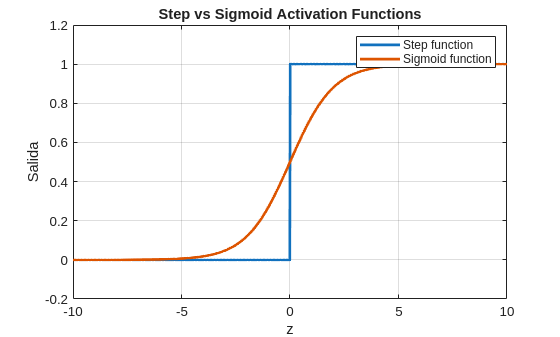

% Rango de valores
z = linspace(-10, 10, 1000);

% Funcion step (Heaviside)
step = double(z >= 0);

% Funcion sigmoide
sigmoid = 1 ./ (1 + exp(-z));

% Grafica
figure;
plot(z, step, 'LineWidth', 2);
hold on;
plot(z, sigmoid, 'LineWidth', 2);
hold off;

% Ajuste del eje y
ylim([-0.2 1.2]);

% Etiquetas y leyenda
xlabel('z');
ylabel('Salida');
legend('Step function', 'Sigmoid function');
title('Step vs Sigmoid Activation Functions');
grid on;

## Sigmoid Function in C